% visualize expression on MST
% Author: Chang Lu
% luchang4104@gmail.com

clear all

% you can put your data folder under 'data' 
currentFolder = pwd;

% datapath = [currentFolder,filesep,'data',filesep,'mix with cd163'];
% or set you own path( replace the sentence above to the example below):
datapath = '/Users/changlu/DATA/OLIVIA/30 clusters CDK5 New'; % your own data path
%datapath = '/Users/changlu/DATA/OLIVIA/PRG4'; % your own data path


addpath(genpath('fun'));
directory = [datapath,filesep,'results',filesep];
if ~exist(directory,'dir')
    mkdir(directory);
end

files=dir(fullfile(datapath));
isub = [files(:).isdir];
fileNames={files(isub).name}';
fileNames(ismember(fileNames,{'.','..','results'})) = [];


## Load data

%check the mat files in the datapath
load([datapath,filesep, 'cosine_kmedoids_k=30']); % add your own mat files
load([datapath,filesep, 'cellmarker_rescale_intergration_t=3']);


## visualization of ki67+ (percentage of + cells), If you have already run 'overlayki67andnuclei', skip this step

ans = '02'

Elapsed time is 0.265742 seconds.


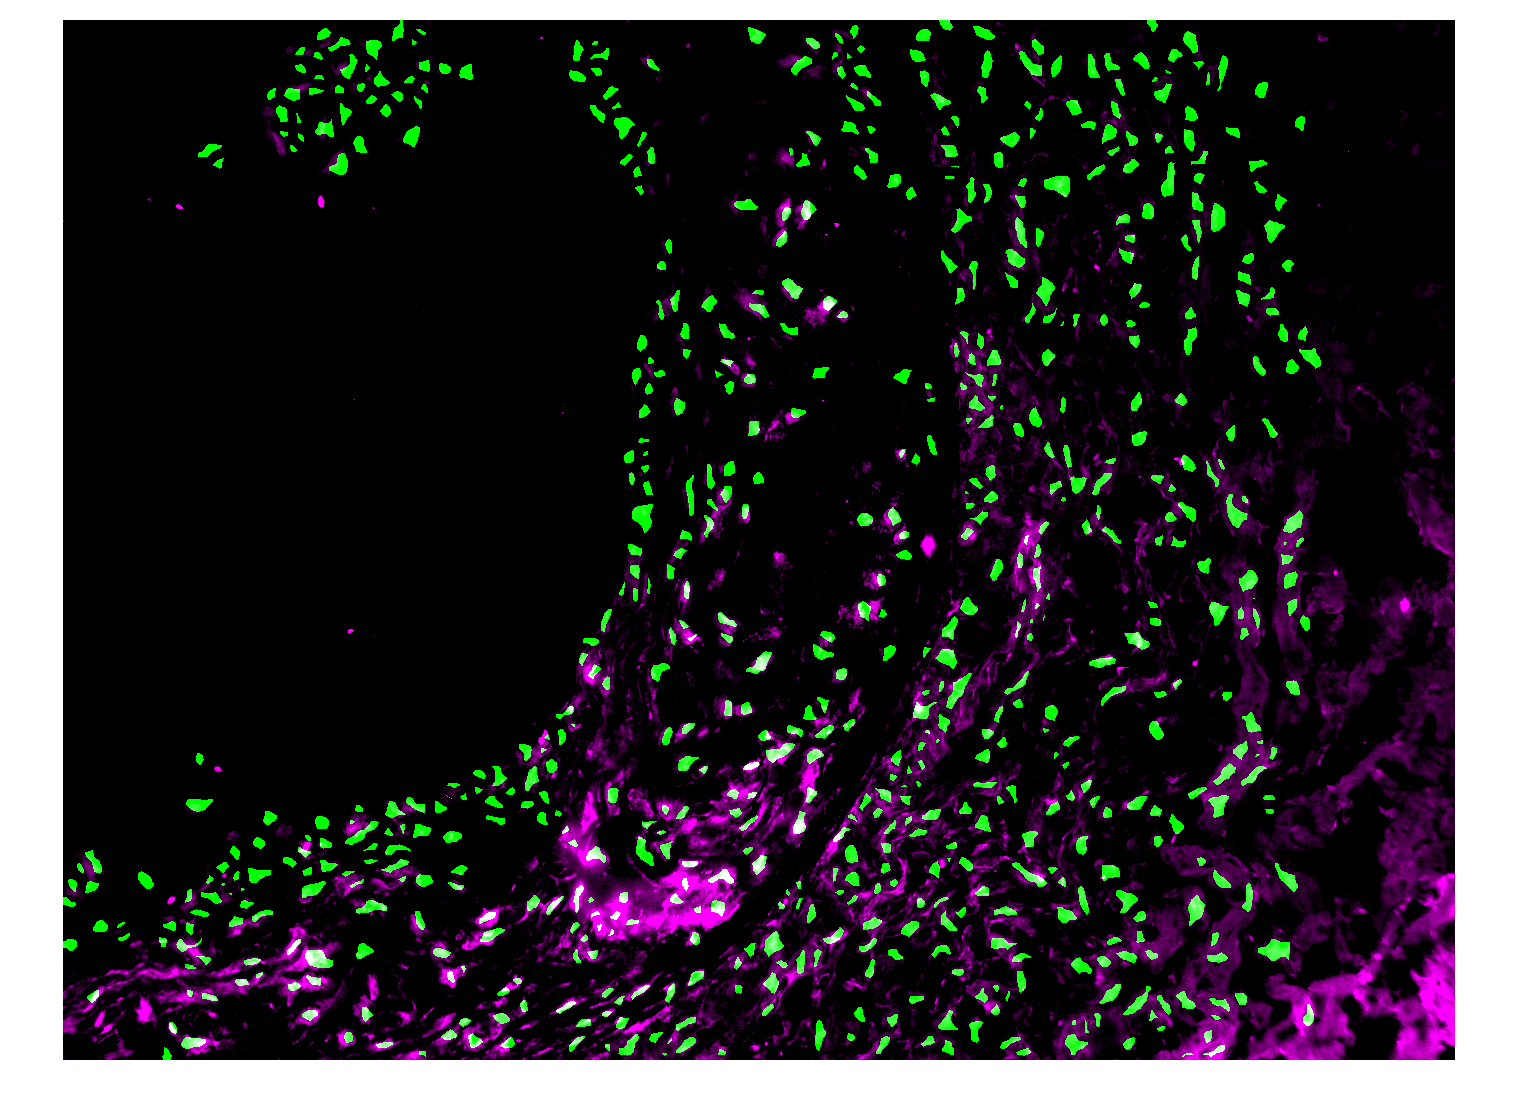

ans = '03'

Elapsed time is 0.161760 seconds.


ans = '04'

Elapsed time is 0.088454 seconds.


ki67pic = 'A_ki67 PE594';
run('script/overlayki67andnuclei');

uni_cluster = unique(labels);
ki=[];
for i= 1:length(fileNames)
    load([datapath,filesep,fileNames{i},filesep,'poski67.mat']);
    ki=[ki;poski67(selected_idx{i})];
end

p=zeros(1,length(uni_cluster));
for i = 1:length(uni_cluster)
    p(i) = sum(ki(labels==uni_cluster(i)))/sum(labels==uni_cluster(i));
end


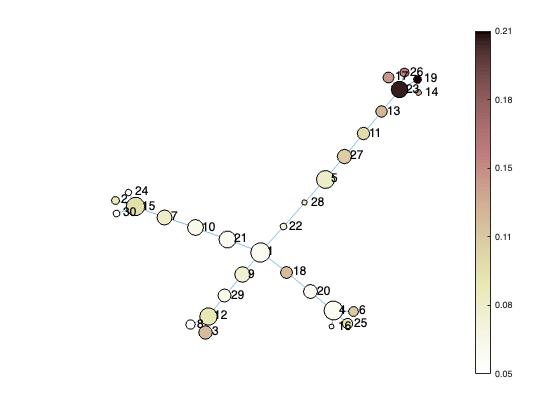

% c = categorical(1:length(uni_cluster));
% figure; bar(c,p);
% xlswrite([directory,'ki67-70.xlsx'],[1:length(uni_cluster);p]);
% 
fig = draw_mst_expr(labels, centers,'cosine',p);
saveas(fig,[directory,'ki67+.jpg'])

## visualization:  intensity of biomarkers on MST (biomarkers for identifying clusters)

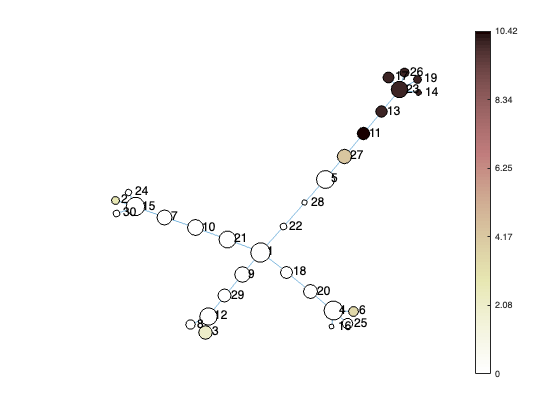

bio_name = 'A_Perilipin2 AF488';
p = centers(:, strcmp(bio_name, biomarkername));
fig = draw_mst_expr(labels, centers,'cosine',p);
figname = 'Perilipin2';
saveas(fig,[directory,figname,'.jpg'])

## visualization:  expression of biomarkers on MST (biomarkers that are not for identifying clusters)

bio_name = 'A_A20 PE-Cy5';
p = aveinten_onMST(fileNames,datapath, bio_name, mix_pos, labels);

fig = draw_mst_expr(labels, centers,'cosine',p);
figname = 'A_A20';
saveas(fig,[directory,figname,'-MST.jpg'])

## visualization:  average intensity per cluster of a biomarker (average prg4 intensity in 20 um radius )

r = 20;
nu_px=0.5; % pixel size = 0.5 um
radii = r/nu_px;
bio_name = 'A_PRG4 AF488';
p = aveinten_onMST_radius(fileNames,datapath, bio_name, mix_pos, radii, labels);


fig = draw_mst_expr(labels, centers,'cosine',p);
figname = 'PRG4';
saveas(fig,[directory,figname,'-MST.jpg'])
